test = readtable("tagliatelle.xlsx",Sheet="Data");

lmis =ismissing(test);

sum(lmis)

ans =      0     7    10


ismissing(test.ash)

ans = 40×1 logical array
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0


fisrcolm = ismissing(test.moisture)

fisrcolm = 40×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


sum(fisrcolm);
% see which rows are missing


test(fisrcolm,:)


ans =

  0×3 empty table

    moisture    ash    broken
    ________    ___    ______




secondcolmiss = ismissing(test.ash)

secondcolmiss = 40×1 logical array
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0


sum(secondcolmiss)

ans = 7

% see which rows are missing
test(secondcolmiss,:)

ans = 7×3 table
    moisture    ash    broken
    ________    ___    ______

      8.65      NaN       8  
      8.25      NaN      13  
      8.45      NaN      15  
       8.2      NaN       8  
      8.65      NaN       6  
      8.45      NaN       8  
       8.5      NaN      13  


thirdcolummiss = ismissing(test.broken);
sum(thirdcolummiss)

ans = 10

% see which rows are missing
disp(test(thirdcolummiss,:));

    moisture    ash     broken
    ________    ____    ______

       8.5      1.01     NaN  
      8.86      1.04     NaN  
       7.6      1.01     NaN  
      10.8      1.06     NaN  
      8.55      1.05     NaN  
       8.4      1.06     NaN  
       8.1      1.03     NaN  
      8.05      1.05     NaN  
      8.85      1.06     NaN  
      8.95      0.99     NaN  



disp(test(secondcolmiss,:));

    moisture    ash    broken
    ________    ___    ______

      8.65      NaN       8  
      8.25      NaN      13  
      8.45      NaN      15  
       8.2      NaN       8  
      8.65      NaN       6  
      8.45      NaN       8  
       8.5      NaN      13  



disp(test(thirdcolummiss,:));

    moisture    ash     broken
    ________    ____    ______

       8.5      1.01     NaN  
      8.86      1.04     NaN  
       7.6      1.01     NaN  
      10.8      1.06     NaN  
      8.55      1.05     NaN  
       8.4      1.06     NaN  
       8.1      1.03     NaN  
      8.05      1.05     NaN  
      8.85      1.06     NaN  
      8.95      0.99     NaN  



% now lets fill the second column missing value
meanvalue = mean(test.ash,"omitmissing");
meanvalue

meanvalue = 1.0279

test.ash(secondcolmiss)=meanvalue;

disp(test(secondcolmiss,:))

    moisture     ash      broken
    ________    ______    ______

      8.65      1.0279       8  
      8.25      1.0279      13  
      8.45      1.0279      15  
       8.2      1.0279       8  
      8.65      1.0279       6  
      8.45      1.0279       8  
       8.5      1.0279      13  



stdthird = std(test.broken,"omitmissing");

stdthird

stdthird = 4.1051

test.broken(thirdcolummiss)=stdthird;

now=ismissing(test);

sum(now)

ans =      0     0     0


test2= readtable("tagliatelle.xlsx",Sheet="Data");

a=ismissing(test2(:,1));
b=ismissing(test2(:,2));
c = ismissing(test2(:,3));

a=sum(a);
b=sum(b);
c=sum(c);

% import the dataset
Xtable=readtable("tagliatelle.xlsx",Sheet="Data");
% compute the matrix of spearman rank-correlation p-values first using
% listwise deletion
% Compute the Spearman rank correlation matrix
corrMatrix = corr(table2array(Xtable), 'Type', 'Spearman', 'Rows', 'complete');
disp(corrMatrix);

    1.0000   -0.0614    0.7429
   -0.0614    1.0000   -0.1584
    0.7429   -0.1584    1.0000



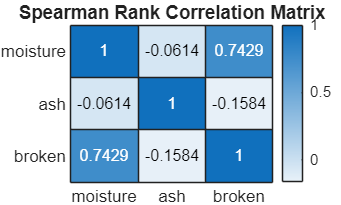

% Now let's visualize the correlation matrix using a heatmap
heatmap(corrMatrix, 'Title', 'Spearman Rank Correlation Matrix', ...
    'XDisplayLabels', Xtable.Properties.VariableNames, ...
    'YDisplayLabels', Xtable.Properties.VariableNames);

XY= readtable("C:\Users\eneay\Downloads\ADMmaggio2021.xlsx",Sheet="FoglioDaImportare",Range="A1:D6");

% COMPUTE THE COORELATION AND CO-RANKING MATRICES(and their p-values) FOR
% three variable under study
% Compute the correlation matrix for the new dataset
column =["Velocit","Prezzo","Giudizio"];

Error using  {}  (line 90)
Unable to concatenate the table variables 'Auto' and 'Velocit', because their types are cell and double.

Error in table2array (line 16)
a = t{:,:};
^^^^^^^^^^^

XY =XY(:,column);

[newCorrMatrix, pValues] = corr(table2array(XY), 'Type', 'Spearman', 'Rows', 'complete');
disp(newCorrMatrix);
disp(pValues);
% Visualize the new correlation matrix using a heatmap
heatmap(newCorrMatrix, 'Title', 'New Spearman Rank Correlation Matrix', ...
    'XDisplayLabels', column, ...
    'YDisplayLabels', column);

% display both matrices the newCorrMatrix and p-values as table object
% Display the correlation and p-values as table objects
corrTable = array2table(newCorrMatrix, 'VariableNames', column, 'RowNames', column);
pValuesTable = array2table(pValues, 'VariableNames', column, 'RowNames', column);

                Velocit    Prezzo     Giudizio
                _______    _______    ________

    Velocit           1        0.7    0.73786 
    Prezzo          0.7          1    0.94868 
    Giudizio    0.73786    0.94868          1 



disp(corrTable);

                Velocit     Prezzo     Giudizio
                _______    ________    ________

    Velocit           1     0.23333         0.2
    Prezzo      0.23333           1    0.066667
    Giudizio        0.2    0.066667           1



disp(pValuesTable);

% show how the linear corelation (co-ranking) cofficent and p-values change
% if all the five car proeces increased by 200 euro or alternatively if
% they all increase by 5%\
% Increase all prices by 2000 euros
increasedPrices = XY.Prezzo + 2000;
% Compute the new correlation matrix with increased prices
newXY = XY;
newXY.Prezzo = increasedPrices;
[newCorrMatrixIncreased, pValuesIncreased] = corr(table2array(newXY), 'Type', 'Spearman', 'Rows', 'complete');

XT = XY{:,:}

XY = 5×3 table
    Velocit    Prezzo    Giudizio
    _______    ______    ________

      230      56000        4    
      220      62000        5    
      150      20000        2    
      195      51000        4    
      253      58000        5    


[R, pValuesa] = corr(XT)